Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\defne\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)


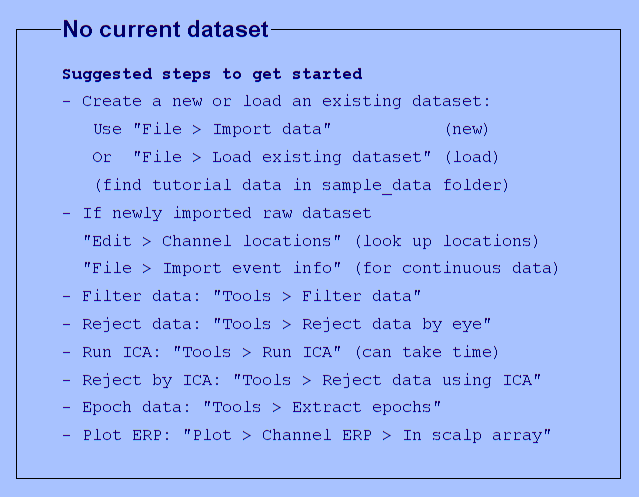

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Extended MATLAB Code for Eye Blink Artifact Removal and Performance Evaluation
% Uses the previously described Wiener filter approach, and then:
% 1) Computes PSD-based performance metrics (D_aa and D_sd) as per the provided formulas.
% 2) Visualizes data using EEGlab.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;
eeglab;

%% Load Training Data
load('Training_EEG.mat');
EEG = train_eeg;
Fs       = 400;   % Sampling frequency
N        = size(EEG,1); % Number of channels
L        = size(EEG,2); % Number of samples

% Parameters for short-time analysis
frameLen = 256;      % Frame length in samples
hopSize  = 128;      % Overlap
numFrames = floor((L - frameLen)/hopSize) + 1;

Y = zeros(N*frameLen, numFrames);
for i = 1:numFrames
    idx = (i-1)*hopSize + (1:frameLen);
    frameData = EEG(:, idx);
    Y(:,i) = frameData(:);
end

% Identify blink frames
blinkFrames = false(1, numFrames);
for i = 1:numFrames
    idx = (i-1)*hopSize + (1:frameLen);
    if any(ismember(idx, blinks))
        blinkFrames(i) = true;
    end
end

Y_blink = Y(:, blinkFrames);
Y_clean = Y(:, ~blinkFrames);

% Estimate covariance matrices
R_yy_blink = (Y_blink*Y_blink.')/size(Y_blink,2);
R_yy_clean = (Y_clean*Y_clean.')/size(Y_clean,2);

% Compute R_xx and R_vv
R_xx = R_yy_blink - R_yy_clean;
R_vv = R_yy_clean;

% Wiener filter
reglambda = 1e-6;
R_yy_blink_reg = R_yy_blink + reglambda*eye(size(R_yy_blink));
H = R_xx / R_yy_blink_reg;

%Test the Filter on the Training Data
EEG_test = EEG;
L_test = size(EEG_test,2);
numFrames_test = floor((L_test - frameLen)/hopSize) + 1;
Y_test = zeros(N*frameLen, numFrames_test);

for i = 1:numFrames_test
    idx = (i-1)*hopSize + (1:frameLen);
    frameData = EEG_test(:, idx);
    Y_test(:,i) = frameData(:);
end

X_hat = H * Y_test; % estimated blink component

EEG_test_clean = zeros(N, L_test);
countFrames = zeros(N, L_test);

for i = 1:numFrames_test
    idx = (i-1)*hopSize + (1:frameLen);
    x_hat_frame = reshape(X_hat(:,i), [N, frameLen]);
    y_frame = reshape(Y_test(:,i), [N, frameLen]);
    v_hat_frame = y_frame - x_hat_frame;
    EEG_test_clean(:, idx) = EEG_test_clean(:, idx) + v_hat_frame;
    countFrames(:, idx) = countFrames(:, idx) + 1;
end
EEG_test_clean = EEG_test_clean ./ max(countFrames,1);
figure()
plot(EEG_test_clean(2,:));


%% Define Segments for Performance Evaluation
% We follow the instructions: use segments just after a blink as "clean."
% For demonstration, let's pick a window around each blink:
blinkWin = 100; % length of segment to analyze around blink (in samples)
cleanOffset = 200; % offset after blink to consider as clean

% Initialize arrays for D_aa and D_sd per blink and channel
% We'll average these later.
D_aa_values = [];
D_sd_values = [];
% Frequency range for PSD calculation (as per instructions, 0-100 Hz)
fRange = [0 100];
tic
for ch = 1:N
    disp(ch);
    for bIdx = 1:length(blinks)
        b = blinks(bIdx);
        
        % Artifact segment: let's take blinkWin samples around the blink
        artStart = max(b - floor(blinkWin/2), 1);
        artEnd   = min(b + floor(blinkWin/2), L_test);
        
        % Clean segment: just after blink occurrence
        clnStart = min(b + cleanOffset, L_test);
        clnEnd   = min(clnStart + blinkWin - 1, L_test);
        
        if clnEnd <= L_test && artEnd <= L_test
            artSeg_orig = EEG_test(ch, artStart:artEnd);
            artSeg_filt = EEG_test_clean(ch, artStart:artEnd);
            
            clnSeg_orig = EEG_test(ch, clnStart:clnEnd);
            clnSeg_filt = EEG_test_clean(ch, clnStart:clnEnd);
            
            % Compute PSD using pwelch for these segments
            [P_art_orig,f] = pwelch(artSeg_orig, [], [], [], Fs);
            [P_art_filt,~] = pwelch(artSeg_filt, [], [], [], Fs);
            
            [P_cln_orig,~] = pwelch(clnSeg_orig, [], [], [], Fs);
            [P_cln_filt,~] = pwelch(clnSeg_filt, [], [], [], Fs);
            
            % Restrict to fRange
            validFreq = (f >= fRange(1)) & (f <= fRange(2));
            P_art_orig = P_art_orig(validFreq);
            P_art_filt = P_art_filt(validFreq);
            P_cln_orig = P_cln_orig(validFreq);
            P_cln_filt = P_cln_filt(validFreq);
            f_sel = f(validFreq);
            
            % Compute D_aa:
            % D_aa = sqrt((1/(2*pi))*∫ [10*log10(P_cln_orig/P_art_filt)]^2 dω)
            % We'll approximate integral by sum. Frequencies f_sel are linear in Hz.
            % The original formula integrates over ω from -π to π, but we have Hz.
            % For simplicity, we assume a scaled version. Here we just do a discrete approximation.
            ratio_aa = P_cln_orig ./ P_art_filt;
            logSpec_aa = (10*log10(ratio_aa)).^2;
            D_aa = sqrt(mean(logSpec_aa));  % Simplified discrete approximation
            
            % Compute D_sd:
            % D_sd = sqrt((1/(2*pi))*∫ [10*log10(P_vv_orig/P_vv_filt)]^2 dω)
            % For D_sd, "artifact-free" segment means P_vv ~ P_cln_orig and filtered ~ P_cln_filt.
            ratio_sd = P_cln_orig ./ P_cln_filt;
            logSpec_sd = (10*log10(ratio_sd)).^2;
            D_sd = sqrt(mean(logSpec_sd));  % Also a simplified approximation
            
            D_aa_values = [D_aa_values; D_aa];
            D_sd_values = [D_sd_values; D_sd];
        end
    end
end

     1



toc
% Overall performance metrics (average across blinks/channels)
mean_D_aa = mean(D_aa_values);
mean_D_sd = mean(D_sd_values);

fprintf('Average D_aa: %.4f\n', mean_D_aa);
fprintf('Average D_sd: %.4f\n', mean_D_sd);

%% Visualizations with EEGlab
% Convert data into EEGlab structure and visualize
% Add path to EEGlab if needed: addpath('path_to_eeglab')
% Then:
% eeglab

% Create EEG structure for original and cleaned data
% We assume a standard 10-20 montage; If channel locations are known, add them.
EEG_orig = pop_importdata('data','EEG_test','nbchan',N,'srate',Fs,'pnts',L_test,'xmin',0);
EEG_orig.data = EEG_test;  % Original

EEG_clean = pop_importdata('data','EEG_test_clean','nbchan',N,'srate',Fs,'pnts',L_test,'xmin',0);
EEG_clean.data = EEG_test_clean; % Cleaned

% If you have channel locations, you can assign them, for example:
% EEG_orig = pop_chanedit(EEG_orig, 'lookup','standard-10-5-cap385.elp');
% EEG_clean = pop_chanedit(EEG_clean, 'lookup','standard-10-5-cap385.elp');

% Visualize raw EEG
pop_eegplot(EEG_orig,1,1,1);
title('Original EEG with Artifacts');

% Visualize cleaned EEG
pop_eegplot(EEG_clean,1,1,1);
title('Cleaned EEG after Artifact Removal');

%BASED ON THE PAPER
load('Training_EEG.mat');
load('Test_EEG.mat');



[cleanedEEG, estimatedArtifacts] = estimateEyeBlinks(train_eeg, 300);

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Error in deneme_eegblink>estimateEyeBlinks (line 265)
        Hn = Un * (Ryy - Rvv) / Ryy;

Related documentation

% Visualize original vs artifact estimation
channel_to_plot = 10; % Choose a channel for visualization
T = 9600;
time_vector = (1:T) / 400; % Time in seconds, assuming Fs = 400 Hz

figure;
subplot(2, 1, 1);
plot(time_vector, cleanedEEG(channel_to_plot, :));
title(['Cleaned EEG Signal (Channel ', num2str(channel_to_plot), ')']);
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(time_vector, estimatedArtifacts(channel_to_plot, :));
title(['Artifact Estimation (Channel ', num2str(channel_to_plot), ')']);
xlabel('Time (s)');
ylabel('Amplitude');
[cleanedEEG_test, estimatedArtifacts_test] = estimateEyeBlinks(test_eeg);
T = size(test_eeg,2);
time_vector = (1:T) / 400;
figure;
subplot(2, 1, 1);
plot(time_vector, cleanedEEG_test(channel_to_plot, :));
title(['Cleaned EEG Signal (Channel ', num2str(channel_to_plot), ')']);
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(time_vector, estimatedArtifacts_test(channel_to_plot, :));
title(['Artifact Estimation (Channel ', num2str(channel_to_plot), ')']);
xlabel('Time (s)');
ylabel('Amplitude');

function [cleanedEEG, estimatedArtifacts, minMSE] = estimateEyeBlinks(eegData, L)
% This function estimates eye blinks in EEG data using a Multichannel Wiener Filter (MWF).
%
% Inputs:
%   eegData - NxT matrix of EEG data (N channels, T samples)
%   samplingRate - Sampling rate of the EEG data (Hz)
%   L - Filter length for Wiener filter
%
% Outputs:
%   cleanedEEG - Artifact-free EEG signal
%   estimatedArtifacts - Estimated eye-blink artifacts
%   minMSE - Minimum Mean Square Error of the cleaned EEG

[N, T] = size(eegData);
frameLength = 300; % Frame length for block processing
hopSize = frameLength / 4; % Overlap of 75%
numFrames = floor((T - frameLength) / hopSize) + 1;

% Initialize output matrices
cleanedEEG = zeros(N, T);
estimatedArtifacts = zeros(N, T);
MSE = zeros(1, numFrames); % Store MSE for each frame

% Process each frame
for frameIdx = 1:numFrames
    startIdx = (frameIdx - 1) * hopSize + 1;
    endIdx = startIdx + frameLength - 1;
    
    % Extract frame
    frame = eegData(:, startIdx:endIdx);
    
    % Compute correlation matrices
    Ryy = frame * frame'; % Observation correlation matrix
    Rvv = estimateRvv(frame); % Estimate Rvv (background EEG)
    
    % Loop through each channel to compute H
    for n = 1:N
        % Define the Un matrix for channel n
        Un = zeros(L, L * N);
        Un(:, (n-1)*L+1:n*L) = eye(L); % Extract the subspace for channel n
        
        % Compute Wiener filter for channel n
        disp(size|(Un))
        Hn = Un * (Ryy - Rvv) / Ryy;
        
        % Estimate artifacts for channel n
        artifacts = Hn * frame(:);
        artifacts = reshape(artifacts, [L, size(frame, 2)]);
        
        % Subtract artifacts from observation
        cleanedFrame = frame(n, :) - artifacts;
        
        % Store cleaned data and artifacts
        cleanedEEG(n, startIdx:endIdx) = cleanedEEG(n, startIdx:endIdx) + cleanedFrame;
        estimatedArtifacts(n, startIdx:endIdx) = estimatedArtifacts(n, startIdx:endIdx) + artifacts;
    end
    
    % Compute MSE for the frame
    MSE(frameIdx) = mean(mean((frame - cleanedFrame).^2));
end

% Normalize overlap-add regions
for i = 1:N
    cleanedEEG(i, :) = cleanedEEG(i, :) / max(cleanedEEG(i, :));
end

% Compute minimum MSE across all frames
minMSE = min(MSE);
end

function Rvv = estimateRvv(frame)
% Estimate Rvv based on non-artifact portions of the frame
% Assuming artifacts are larger and less stationary compared to EEG
Rvv = zeros(size(frame, 1));
meanFrame = mean(frame, 2);
for i = 1:size(frame, 2)
    if norm(frame(:, i) - meanFrame) < 2 * std(frame(:))
        Rvv = Rvv + frame(:, i) * frame(:, i)';
    end
end
Rvv = Rvv / size(frame, 2);
end






